# USV Surge Response - HW2

In part a) you should have come up with an equation of motion in the time-domain

$M \dot{u}(t)+ D u(t) = T(t)$.

## Part b

Consider the scenario where the vessel starts at rest with no input. At time zero the input thrust is set to a constant 37.5 N.

We need to solve this first-order ODE with a step function forcing term: $T(t) = T_o \mu(t) = 37.5 \mu(t)$where $\mu(t)$ is the unit step function.   Taking the Laplace transform of the entire equation yields

$M \left( s U(s) - u(0)\right) + D ((s) = \frac{37.5}{s}$.

We are given that the vessel starts at rest, so $u(0) = 0$.   Solving for $U(s)$


$$U(s) = \frac{1}{Ms+D} \, \frac{37.5}{s}$$


To find the *solution* to the ODE, we need to use the inverse Laplace transform to convert the solution for the surge velocity back to the time domain.  We can do this using the PFE

To = 37.5;
M = 36;
D = 18.75;
[r,p,k]=residue(To,[M, D, 0])

r =     -2
     2


p =    -0.5208
         0



k =

     []



 and should get the expression


$$u(t) = 2 (\left(1-e^{-0.52 \, t} \, \right) =\frac{T_o}{D} \, \left(1 - e^{t/(M/D)}\,\right) = 2\, \left(1 - e^{t/\tau}\,\right)$$


(Foreshadowing next week, we can see that the *time constant*, $\tau$, is $\tau = M/D = 1.92 \, s$

To graph the time response, evaluate the time domain surge equation over a vector of times

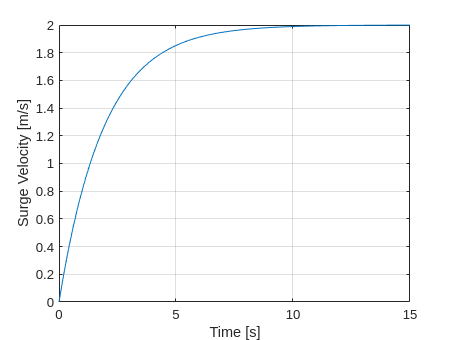

tt = linspace(0,15,100);
tau = M/D;
uu = (A/D)*(1-exp(-tt/tau));
figure(1)
clf()
plot(tt,uu)
grid on;
xlabel('Time [s]')
ylabel('Surge Velocity [m/s]')

Find how long it takes for the surge response to reach 95% of the final vlaue.   

You can do this manually by looking at the graph.  The final value is 2 m/s, so we are looking for the first time that the surge exceeds 1.9 m/s, which looks to be about 6 seconds.   We can add a marker to the plot to visualize this estimate:

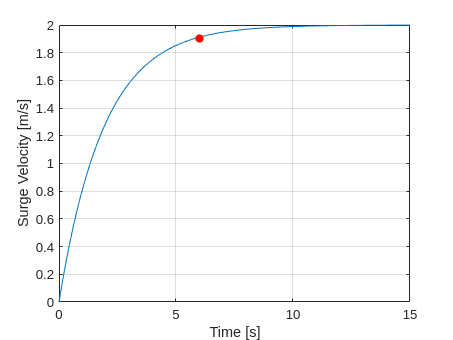

hold on
plot(6, 1.9, 'o', 'MarkerFaceColor','red')

We can be more exact by using MATLAB's find function

Steady state value for the response is 

uss = To/D

uss = 2

Find the first index where value of the response that exceed 95% of the steady-state

II = find(uu >= 0.95 * uss, 1)

II = 39

Now find the time and response values that correspond to that index 

t95 = tt(II)

t95 = 5.7576

u95 = uu(II)

u95 = 1.9003

and plot this point on the graph

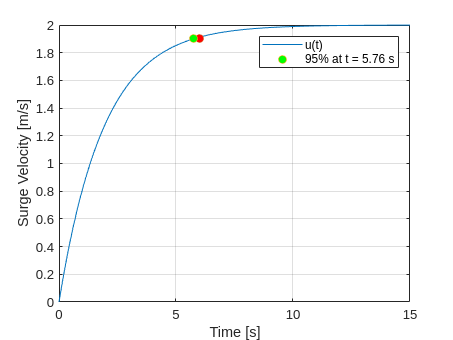

plot(t95, u95,'o','markerfacecolor','g')
legend('u(t)','', sprintf('95%% at t = %.2f s',t95))